# Spatiotemporal Energy Model 3: Dot Stimuli

By: Linjing & Qihan

This file is the same as tutorial, but changes the image inputs to drifting dot stimuli.

## Initialization

To start, let's clean the workspace:

clear all
close all
clc

Define the spatial and temporal sampling scale

% time sampling
deltaT = 10; % ms, temporal sampling step
duration = 1000; % ms, temporal sampling duration
t = 0:deltaT:(duration-deltaT); % temporal sampling vector

% spatial sampling: 2D image
deltaX = 0.02; % deg, spatial sampling step
x = -2:deltaX:2; y = x'; % spatial sampling matrix for x and y dimension

% creating grids for later processing
[Y,X,T] = ndgrid(x,y,t);
[X1,Y1] = meshgrid(x,y);

Define the number of stimuli (K) you wanna test (up to four stimuli)

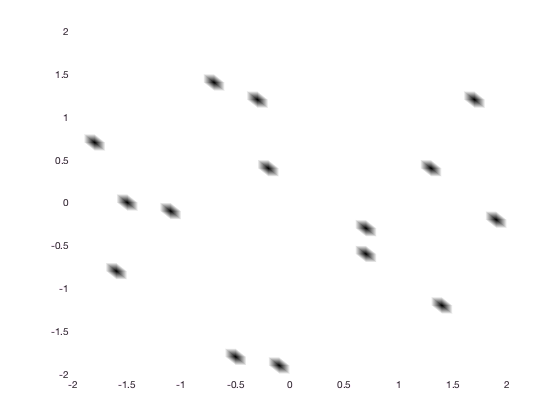

K = 1; % from 1 to 4

Define the time constant of the temporal filter

tau = 25; % time constant, ms

## Generate stimulus

Construct dirfting dot stimuli moving toward four directions. Be aware: you need the "mkDots" function provided by the MT model (Heeger 1997)

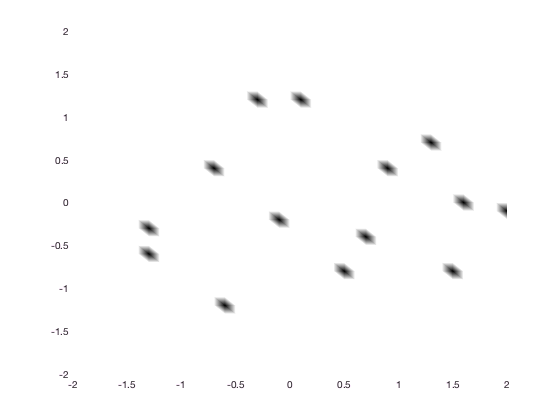

dir = [-pi/2,pi/2,pi,0]; % direction of the dot
speed = 1; % speed of the dot
congruency = 0.99; % coherence level
stimUp = mkDots([length(x) length(y) length(t)],dir(1),speed,congruency);
stimDown = mkDots([length(x) length(y) length(t)],dir(2),speed,congruency);
stimLeft = mkDots([length(x) length(y) length(t)],dir(3),speed,congruency);
stimRight = mkDots([length(x) length(y) length(t)],dir(4),speed,congruency);


dotStim = {stimLeft stimRight stimUp stimDown};


Show the stimulus dynamically

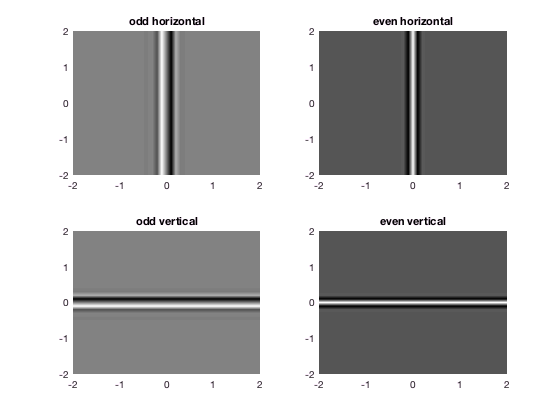

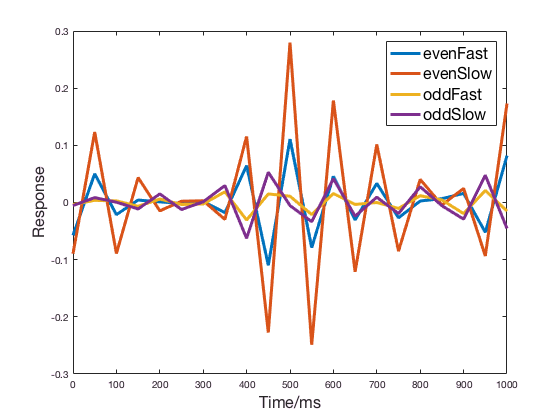

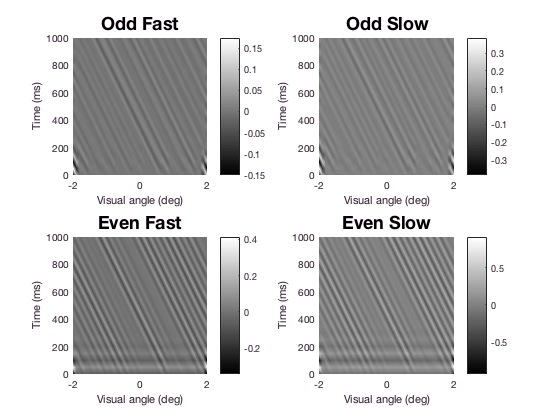

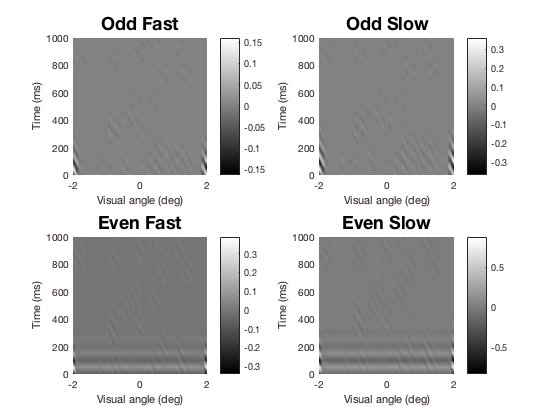

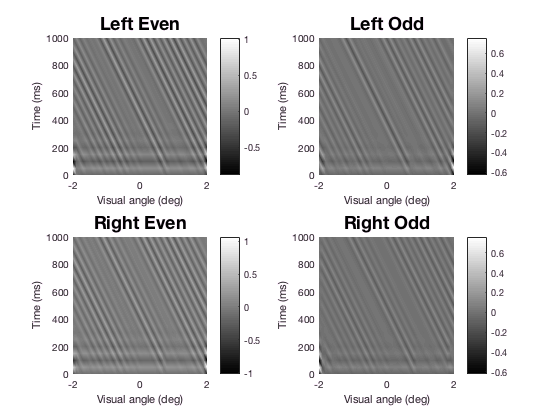

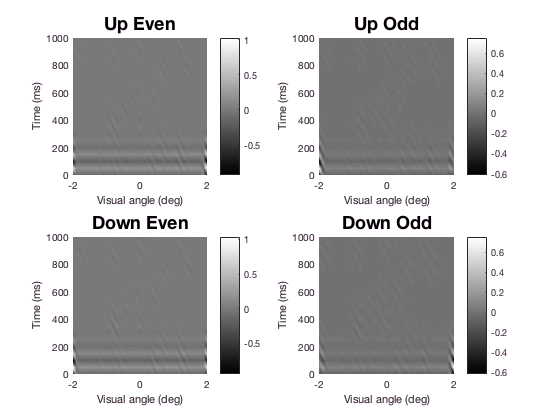

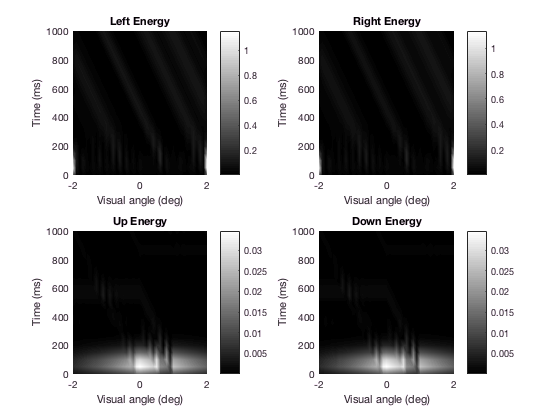

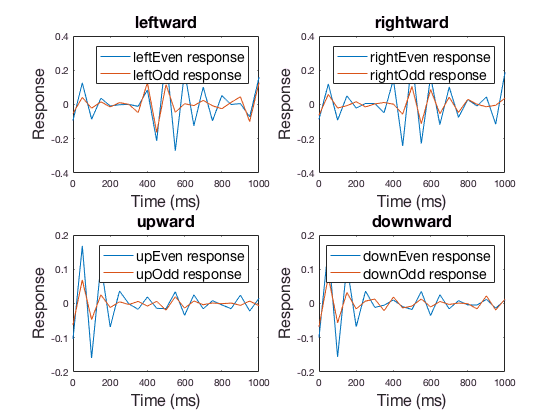

figure

S = dotStim{1}; 
for ii = 1:length(t)
    surf(X1,Y1,squeeze(S(:,:,ii)))
    colormap gray
    shading interp
    view(2)
    drawnow
end

## Construct spatial filters

We construct four Gabor filters for two spatial dimensions and two phases. 

Define some common parameters of these Gabor filters. There are another two parameters (sD_gabor and sP_gabor), which you can change later to construct filters with different direction and phases.

sigma = 0.1; % spread of Gaussian window, deg
sf_gabor = 4; % spatial frequency of the sinusoid window, cyc/deg
sC_gabor = 1; % scale factor
sP_gabor = 0; % Phase: period


Construct a horizontal filter with even phase

sD_gabor = 0; % direction of the Gabor filter: 0, rightward, 90, upward
sP_gabor = 0; % Phase: even (0, 0.5, 1), odd (0.25, 0.75)
evenFiltH = sC_gabor .* exp(-(x.^2)./(2*sigma^2)) .* ...
    cos(2*pi*(sf_gabor.*(cosd(sD_gabor).*X1 + sind(sD_gabor).*Y1) + sP_gabor));

Construct a horizontal filter with odd phase

sD_gabor = 0; % direction of the Gabor filter
sP_gabor = 0.25; % Phase
oddFiltH = sC_gabor .* exp(-(x.^2)./(2*sigma^2)) .* ...
    cos(2*pi*(sf_gabor.*(cosd(sD_gabor).*X1 + sind(sD_gabor).*Y1) + sP_gabor));

Construct a vertical filter with even phase

sD_gabor = 90; % direction of the Gabor filter
sP_gabor = 0; % Phase
evenFiltV = sC_gabor .* exp(-(y.^2)./(2*sigma^2)) .* ...
    cos(2*pi*(sf_gabor.*(cosd(sD_gabor).*X1 + sind(sD_gabor).*Y1) + sP_gabor));

Construct a vertical filter with odd phase

sD_gabor = 90; % direction of the Gabor filter
sP_gabor = 0.25; % Phase
oddFiltV = sC_gabor .* exp(-(y.^2)./(2*sigma^2)) .* ...
    cos(2*pi*(sf_gabor.*(cosd(sD_gabor).*X1 + sind(sD_gabor).*Y1) + sP_gabor));

Normalization of these filters

integral1 = sum(sum(evenFiltH.^2 + oddFiltH.^2)); 
integral2 = sum(sum(evenFiltV.^2 + oddFiltV.^2));

evenFiltH = evenFiltH./integral1; % horizontal-preferred, even-phase filter
oddFiltH = oddFiltH./integral1; % horizontal-preferred, odd-phase filter
evenFiltV = evenFiltV./integral2; % vertical-preferred, even-phase filter
oddFiltV = oddFiltV./integral2; % vertical-preferred, odd-phase filter


Show the four filters

figure
subplot(2,2,1)
surf(X1,Y1,oddFiltH)
colormap gray
shading interp
view(2)
title('odd horizontal')
drawnow

subplot(2,2,2)
surf(X1,Y1,evenFiltH)
colormap gray
shading interp
view(2)
title('even horizontal')
drawnow

subplot(2,2,3)
surf(X1,Y1,oddFiltV)
colormap gray
shading interp
view(2)
title('odd vertical')
drawnow

subplot(2,2,4)
surf(X1,Y1,evenFiltV)
colormap gray
shading interp
view(2)
title('even vertical')

## Convolution with temporal and spatial filters sequentially and get spatiotemporally separable impulse responses

Do some matrix initialization

y1 = zeros(length(x)); y2 = y1; y3 = y1; y4 = y1; y5 = y1; y6 = y1; y7 = y1;
f1 = y1; f2 = y1; f1Save = repmat(y1,1,1,length(t)); f2Save = f1Save;
fastFilt = cell(4,1); slowFilt = cell(4,1);


Convolution

for ii = 1:K
    S = dotStim{ii};
    for tt = 1:length(t)
        % temporal convolution with a cascade of exponential low-pass filter
        deltaY1 = (deltaT./tau) .* (-y1 + S(:,:,tt)); y1 = y1 + deltaY1;
        deltaY2 = (deltaT./tau) .* (-y2 + y1); y2 = y2 + deltaY2;
        deltaY3 = (deltaT./tau) .* (-y3 + y2); y3 = y3 + deltaY3;
        deltaY4 = (deltaT./tau) .* (-y4 + y3); y4 = y4 + deltaY4;
        deltaY5 = (deltaT./tau) .* (-y5 + y4); y5 = y5 + deltaY5;
        deltaY6 = (deltaT./tau) .* (-y6 + y5); y6 = y6 + deltaY6;
        deltaY7 = (deltaT./tau) .* (-y7 + y6); y7 = y7 + deltaY7;
        f1 = y3 - y5; f1Save(:,:,tt) = f1; % fast responses
        f2 = y5 - y7; f2Save(:,:,tt) = f2; % slow responses
        
        % spatial convolution with four gabor filters
        oFV(:,:,tt) = conv2(f1,oddFiltV,'same');
        oSV(:,:,tt) = conv2(f2,oddFiltV,'same');
        eFV(:,:,tt) = conv2(f1,evenFiltV,'same');
        eSV(:,:,tt) = conv2(f2,evenFiltV,'same');
        oFH(:,:,tt) = conv2(f1,oddFiltH,'same');
        oSH(:,:,tt) = conv2(f2,oddFiltH,'same');
        eFH(:,:,tt) = conv2(f1,evenFiltH,'same');
        eSH(:,:,tt) = conv2(f2,evenFiltH,'same');
    end
    % put these results into different structures
    fastFilt{ii} = f1Save; slowFilt{ii} = f2Save;
    oddFastV{ii} = oFV; oddSlowV{ii} = oSV; evenFastV{ii} = eFV; evenSlowV{ii} = eSV;
    oddFastH{ii} = oFH; oddSlowH{ii} = oSH; evenFastH{ii} = eFH; evenSlowH{ii} = eSH;
end

From convolution, we get eight spatiotemporally seprable impulse responses (two spatial dimensions x two temporal dynamics x two phases). Let's draw these responses in two different ways. 

- First, we look at the temporal evolution of impulse responses for one neuron. Here, I took the neuron at the central position of the image

m = floor(length(x)/2); % Index for the spatial position of the neuron
n = length(t)/2; % Index for the length of time window showed in the figure
X2 = squeeze(X(m,:,:))'; % X
T2 = squeeze(T(m,:,:))'; % T
Y2 = squeeze(Y(:,m,:))'; % Y

figure
plot(t(1:n),squeeze(eFH(m,m,1:n)),'lineWidth',3);
hold on
plot(t(1:n),squeeze(eSH(m,m,1:n)),'lineWidth',3);
hold on
plot(t(1:n),squeeze(oFH(m,m,1:n)),'lineWidth',3);
hold on
plot(t(1:n),squeeze(oSH(m,m,1:n)),'lineWidth',3);
legend({'evenFast','evenSlow','oddFast','oddSlow'},'fontsize',16)
xlabel('Time/ms','fontsize',16)
ylabel('Response','fontsize',16)

-  We took the x-t slice of four horizontal responses. Here we fix Y at 2 deg (you can change this value in 'm')

m = floor(length(x)/2); % Index for the fixed Y position

for ii = 1:K
figure
subplot(2,2,1)
a = oddFastH{ii};
a = squeeze(a(m,:,:))'; 
surf(X2,T2,a)
colormap gray
shading interp
view(2)
xlabel('Visual angle (deg)')
ylabel('Time (ms)')
title('Odd Fast Horizontal','fontsize',18)
colorbar
shg

subplot(2,2,2)
a = oddSlowH{ii};
a = squeeze(a(m,:,:))';  
surf(X2,T2,a)
colormap gray
shading interp
view(2)
xlabel('Visual angle (deg)')
ylabel('Time (ms)')
title('Odd Slow Horizontal','fontsize',18)
colorbar
shg

subplot(2,2,3)
a = evenFastH{ii};
a = squeeze(a(m,:,:))'; 
surf(X2,T2,a)
colormap gray
shading interp
view(2)
xlabel('Visual angle (deg)')
ylabel('Time (ms)')
title('Even Fast Horizontal','fontsize',18)
colorbar
shg

subplot(2,2,4)
a = evenSlowH{ii};
a = squeeze(a(m,:,:))'; 
surf(X2,T2,a)
colormap gray
shading interp
view(2)
xlabel('Visual angle (deg)')
ylabel('Time (ms)')
title('Even Slow Horizontal','fontsize',18)
colorbar
end
 

- We can also take the y-t slice of four vertical responses. Here we fix X at 2 deg (we can change this value in 'm')

m = floor(length(x)/2); % Index for the fixed Y position

for ii = 1:K
    figure
subplot(2,2,1)
a = oddFastV{ii};
a = squeeze(a(:,m,:))'; 
surf(Y2,T2,a)
colormap gray
shading interp
view(2)
xlabel('Visual angle (deg)')
ylabel('Time (ms)')
title('Odd Fast Vertical','fontsize',18)
shg
colorbar

subplot(2,2,2)
a = oddSlowV{ii};
a = squeeze(a(:,m,:))'; 
surf(Y2,T2,a)
colormap gray
shading interp
view(2)
xlabel('Visual angle (deg)')
ylabel('Time (ms)')
title('Odd Slow Vertical','fontsize',18)
shg
colorbar

subplot(2,2,3)
a = evenFastV{ii};
a = squeeze(a(:,m,:))'; 
surf(Y2,T2,a)
colormap gray
shading interp
view(2)
xlabel('Visual angle (deg)')
ylabel('Time (ms)')
title('Even Fast Vertical','fontsize',18)
shg
colorbar

subplot(2,2,4)
a = evenSlowV{ii};
a = squeeze(a(:,m,:))'; 
surf(Y2,T2,a)
colormap gray
shading interp
view(2)
xlabel('Visual angle (deg)')
ylabel('Time (ms)')
title('Even Slow Vertical','fontsize',18)
colorbar
end


## Get spatiotemporally oriented impulse response

We can combine eight spatiotemporally separable responses as indicated by Adelson and Bergen (1985), and get  eight spatiotemporally oriented impulse response (four directions x two phases). These oriented responses are direction-selective, but also phase-selectiv. 

for ii = 1:K
  % direction-selective and phase-sensitive impulse response
    downEven{ii} = oFV + eSV;
    downOdd{ii} = -oSV + eFV;
    upEven{ii} = -oFV + eSV;
    upOdd{ii} = oSV + eFV;
    leftEven{ii} = oFH + eSH;
    leftOdd{ii} = -oSH + eFH;
    rightEven{ii} = -oFH + eSH;
    rightOdd{ii} = oSH + eFH;
    
    % direction-selective and phase-insensitive impulse response
    downEnergy{ii} = downEven{ii}.^2 + downOdd{ii}.^2;
    upEnergy{ii} = upEven{ii}.^2 + upOdd{ii}.^2;
    leftEnergy{ii} = leftEven{ii}.^2 + leftOdd{ii}.^2;
    rightEnergy{ii} = rightEven{ii}.^2 + rightOdd{ii}.^2;
end

Similar with previous section, we can still draw the response in two ways

- look at the temporal evolution of oriented responses for one neuron

n = 1:length(t); % index for the time window presented
m = floor(length(x)/2); % spatial position of the neuron

for ii = 1:K 
figure
subplot(2,2,1)
a = leftEven{ii};
b = leftOdd{ii};
c1 = squeeze(a(m,m,n));
c2 = squeeze(b(m,m,n));
plot(t(n),c1,t(n),c2)
xlabel('Time (ms)','FontSize',16)
ylabel('Response','FontSize',16)
title('leftward','FontSize',16)
legend({'leftEven response','leftOdd response'},'FontSize',14)

subplot(2,2,2)
a = rightEven{ii};
b = rightOdd{ii};
c = rightEnergy{ii};
c1 = squeeze(a(m,m,n));
c2 = squeeze(b(m,m,n));
plot(t(n),c1,t(n),c2)
xlabel('Time (ms)','FontSize',16)
ylabel('Response','FontSize',16)
title('rightward','FontSize',16)
legend({'rightEven response','rightOdd response'},'FontSize',14)

subplot(2,2,3)
a = upEven{ii};
b = upOdd{ii};
c = upEnergy{ii};
c1 = squeeze(a(m,m,n));
c2 = squeeze(b(m,m,n));
plot(t(n),c1,t(n),c2)
xlabel('Time (ms)','FontSize',16)
ylabel('Response','FontSize',16)
title('upward','FontSize',16)
legend({'upEven response','upOdd response'},'FontSize',14)

subplot(2,2,4)
a = downEven{ii};
b = downOdd{ii};
c = downEnergy{ii};
c1 = squeeze(a(m,m,n));
c2 = squeeze(b(m,m,n));
plot(t(n),c1,t(n),c2)
xlabel('Time (ms)','FontSize',16)
ylabel('Response','FontSize',16)
title('downward','FontSize',16)
legend({'downEven response','downOdd response'},'FontSize',14)
end

- took the x-t slice of the horizontal oriented responses

m = floor(length(x)/2); % Fixed Y position
X2 = squeeze(X(m,:,:))';
T2 = squeeze(T(m,:,:))';

for ii = 1:K
figure
subplot(2,2,1)
b = leftEven{ii};
b = squeeze(b(m,:,:))'; 
surf(X2,T2,b)
colormap gray
shading interp
view(2)
xlabel('Visual angle (deg)')
ylabel('Time (ms)')
title('Left Even','fontsize',18)
colorbar
shg

subplot(2,2,2)
b = leftOdd{ii};
b = squeeze(b(m,:,:))'; %T2 = flipud(T2);
surf(X2,T2,b)
colormap gray
shading interp
view(2)
xlabel('Visual angle (deg)')
ylabel('Time (ms)')
title('Left Odd','fontsize',18)
shg
colorbar

subplot(2,2,3)
b = rightEven{ii};
b = squeeze(b(m,:,:))'; %a = flipud(a); T2 = flipud(T2);
surf(X2,T2,b)
colormap gray
shading interp
view(2)
xlabel('Visual angle (deg)')
ylabel('Time (ms)')
title('Right Even','fontsize',18)
shg
colorbar

subplot(2,2,4)
b = rightOdd{ii};
b = squeeze(b(m,:,:))'; %a = fliplr(a); T2 = flipud(T2);
surf(X2,T2,b)
colormap gray
shading interp
view(2)
xlabel('Visual angle (deg)')
ylabel('Time (ms)')
title('Right Odd','fontsize',18)
colorbar
end

- took the y-t slice of the vertical oriented responses

m = floor(length(x)/2); % Fixed X position
Y2 = squeeze(Y(:,m,:))';
T2 = squeeze(T(:,m,:))';

for ii = 1:K
figure
subplot(2,2,1)
b = upEven{ii};
b = squeeze(b(:,m,:))'; 
surf(Y2,T2,b)
colormap gray
shading interp
view(2)
xlabel('Visual angle (deg)')
ylabel('Time (ms)')
title('Up Even','fontsize',18)
colorbar
shg

subplot(2,2,2)
b = upOdd{ii};
b = squeeze(b(:,m,:))'; %T2 = flipud(T2);
surf(Y2,T2,b)
colormap gray
shading interp
view(2)
xlabel('Visual angle (deg)')
ylabel('Time (ms)')
title('Up Odd','fontsize',18)
colorbar
shg

subplot(2,2,3)
b = downEven{ii};
b = squeeze(b(:,m,:))'; 
surf(Y2,T2,b)
colormap gray
shading interp
view(2)
xlabel('Visual angle (deg)')
ylabel('Time (ms)')
title('Down Even','fontsize',18)
colorbar
shg

subplot(2,2,4)
b = downOdd{ii};
b = squeeze(b(:,m,:))'; 
surf(Y2,T2,b)
colormap gray
shading interp
view(2)
xlabel('Visual angle (deg)')
ylabel('Time (ms)')
title('Down Odd','fontsize',18)
colorbar
end

## Get spatiotemporally oriented energy

Finally, we can square and summate two oriented responses with same direction selectivity, but different phases, to get four spatiotemporally oriented energy. These energy responses are still direction selective, but now phase insensitive.

for ii = 1:K
    % direction-selective and phase-insensitive impulse response
    downEnergy{ii} = downEven{ii}.^2 + downOdd{ii}.^2;
    upEnergy{ii} = upEven{ii}.^2 + upOdd{ii}.^2;
    leftEnergy{ii} = leftEven{ii}.^2 + leftOdd{ii}.^2;
    rightEnergy{ii} = rightEven{ii}.^2 + rightOdd{ii}.^2;
end


Draw these energies in two ways as previous sections:

- the temporal evolution of the energy responses of one neuron

n = 1:length(t); % time window
m = floor(length(x)/2); % index for spatial position of the image

for ii = 1:K 
figure
subplot(2,2,1)
c = leftEnergy{ii};
c3 = squeeze(c(m,m,n));
plot(t(n),c3)
xlabel('Time (ms)','FontSize',16)
ylabel('Response','FontSize',16)
title('leftward energy','FontSize',16)

subplot(2,2,2)
c = rightEnergy{ii};
c3 = squeeze(c(m,m,n));
plot(t(n),c3)
xlabel('Time (ms)','FontSize',16)
ylabel('Response','FontSize',16)
title('rightward energy','FontSize',16)

subplot(2,2,3)
c = upEnergy{ii};
c3 = squeeze(c(m,m,n));
plot(t(n),c3)
xlabel('Time (ms)','FontSize',16)
ylabel('Response','FontSize',16)
title('upward energy','FontSize',16)

subplot(2,2,4)
c = downEnergy{ii};
c3 = squeeze(c(m,m,n));
plot(t(n),c3)
xlabel('Time (ms)','FontSize',16)
ylabel('Response','FontSize',16)
title('downward energy','FontSize',16)
end

- the x-t slice of the horizontal energy responses, and the y-t slice of the vertical energy responses

m = floor(length(x)/2); % Index for the spatial position of the image
 
for ii = 1:K
figure
subplot(2,2,1)
a = leftEnergy{ii};
a = squeeze(a(m,:,:))'; %T = flipud(T);
surf(X2,T2,a)
colormap gray
shading interp
view(2)
xlabel('Visual angle (deg)')
ylabel('Time (ms)')
title('Left Energy')
colorbar
shg

subplot(2,2,2)
a = rightEnergy{ii};
a = squeeze(a(m,:,:))'; %T = flipud(T);
surf(X2,T2,a)
colormap gray
shading interp
view(2)
xlabel('Visual angle (deg)')
ylabel('Time (ms)')
title('Right Energy')
colorbar
shg

subplot(2,2,3)
a = upEnergy{ii};
a = squeeze(a(:,m,:))'; %a = flipud(a); T = flipud(T);
surf(X2,T2,a)
colormap gray
shading interp
view(2)
xlabel('Visual angle (deg)')
ylabel('Time (ms)')
title('Up Energy')
colorbar
shg

subplot(2,2,4)
a = downEnergy{ii};
a = squeeze(a(:,m,:))'; %a = fliplr(a); T = flipud(T);
surf(X2,T2,a)
colormap gray
shading interp
view(2)
xlabel('Visual angle (deg)')
ylabel('Time (ms)')
title('Down Energy')
colorbar
end
